clear all;
syms t X Y Ut(x,y) U(x,y)
G   = 6.674e-11;
Ms  = 1.989e30;
Mj  = 1.898e27;
Me  = 5.972e24;
Mm  = 7.347e22;
Rj0 = 7.770e11;
Re0 = 1.496e11;
Rm0 = 3.840e8;
Vj0 = 13.1e3;
Ve0 = 29.8e3;
Vm0 = 1.03e3;
Oj0 = Vj0/Rj0;
Oe0 = Ve0/Re0;
Om0 = Vm0/Rm0;
Xe  = - Mm*Rm0/Me;
Ye  = 0;
Xm  = Rm0;
Ym  = 0;

reserr = 2;
res = 1e7;
x = -1e9:res:1e9;
y = -1e9:res:1e9;
[Xd,Yd] = meshgrid(x,y);


U(X,Y) =  -.5*(X^2+Y^2)*Om0^2-G.*(Me/sqrt((Xe-X)^2+(Ye-Y)^2)+Mm/sqrt((Xm-X)^2+(Ym-Y)^2));
UMat = matlabFunction(U);
Z = UMat(Xd,Yd);

eqU_partial_diff_x = diff(U,X);
eqU_partial_diff_y = diff(U,Y);
M = solve(eqU_partial_diff_x,eqU_partial_diff_y);

Md = [double(M.X) double(M.Y)];
MLM = Md(((Md(:,1).*conj(Md(:,1))==Md(:,1).^2)& (Md(:,2).*conj(Md(:,2))==Md(:,2).^2)),:);
MLM = MLM((abs(double(eqU_partial_diff_x(MLM(:,1),MLM(:,2))))<.001)& ...
          (abs(double(eqU_partial_diff_y(MLM(:,1),MLM(:,2))))<.001),:);

[Sxx,Ix] = sort(MLM(:,1));
[Syy,Iy] = sort(MLM(:,2));
MLM = intersect( ...
    MLM([Ix(~(abs(diff(MLM(Ix,2)))<reserr*res&abs(diff(Sxx))<reserr*res));Ix(end)],:), ...
    MLM([Iy(~(abs(diff(MLM(Iy,1)))<reserr*res&abs(diff(Syy))<reserr*res));Iy(end)],:),'rows')

MLM = 1.0e+08 *

   -3.8398         0
    1.8964   -3.2975
    1.8964    3.2975
    3.2394         0
    4.4651         0


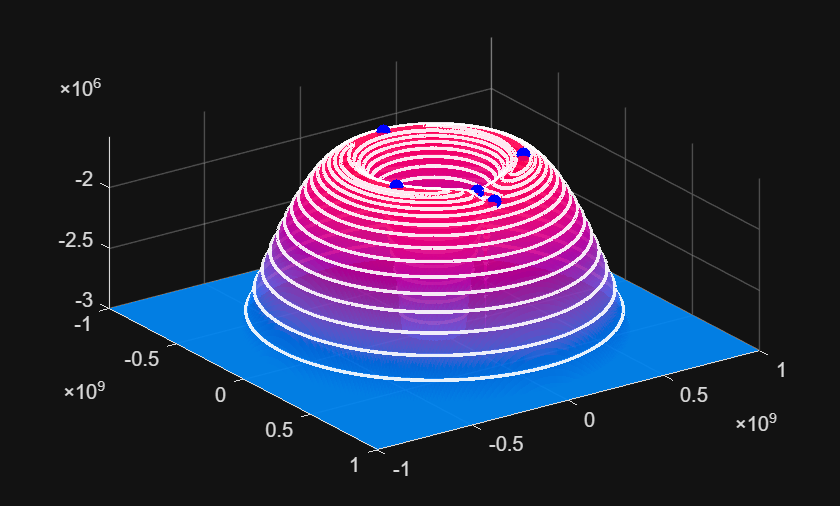


colormap nebula;
axis tight;
Zc = (clip(Z,-3e6,0));
surf(Xd,Yd,Zc,'EdgeColor','none', 'FaceAlpha',0.9);
hold on;
contour3(Xd,Yd,Zc,prctile(Zc(:),100*(.01:.05:1).^.5),'w','LineWidth',2,'EdgeAlpha',0.9);
scatter3(MLM(:,1),MLM(:,2), Zc(ismembertol([Xd(:) Yd(:)],MLM,.005,'ByRows',true)),50,'bo','filled');
hold off;
view([55 45])